# Olympus Oir 读入器

构造

Reader=Image5D.OirReader("C:\Users\vhtmf\Desktop\0015.202205100855.BlueAudioWater.3%350V20%350V.oir");

获取各项属性

Reader.SizeX %图像宽度

ans = uint16
512

Reader.SizeY %图像高度

ans = uint16
512

Reader.SizeC %颜色通道数

ans = uint8
3

Reader.SizeZ %Z层数

ans = uint8
2

Reader.SizeT %时间周期

ans = uint16
679

Reader.SeriesInterval %每个时间周期实际经历的毫秒数

ans = single
124.7148

[Devices,Colors]=Reader.DeviceColors %各通道设备名称和颜色信息

Devices = 3×1 string 数组
    "RNDD4G"
    "CD1"
    "CD2"


Colors = 3×3 single 矩阵
     0     1     0
     1     1     1
     1     1     1


读入像素，ReadPixels有4种语法：

Image=Reader.ReadPixels; %读入全部像素值
Image=Reader.ReadPixels(0,100); %指定读入的起始时间（从0开始）和时间尺寸，CZ维度会自动全部读入
Image=Reader.ReadPixels(0,100,0); %额外选定一个通道，0开始
Image=Reader.ReadPixels(0,100,0,2,0,1); %指定起始时间、时间尺寸、起始Z层、Z层尺寸、起始通道、通道尺寸

Image的维度顺序为XYCZT，数据类型uint16

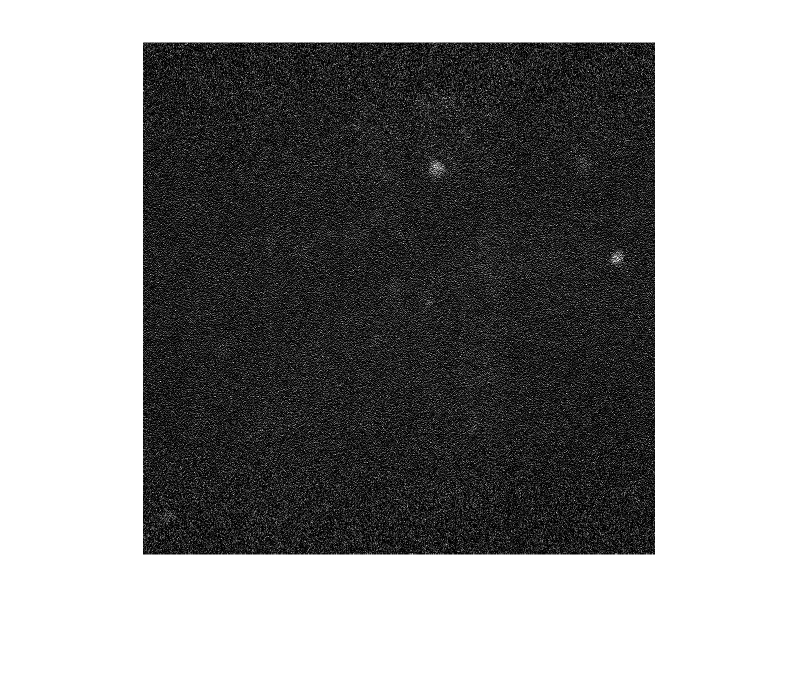

imshow(Image(:,:,1,1,1),[]);

# Ome Tiff 读写器

创建

import Image5D.*
OmeTiff=OmeTiffRWer.Create("图像.tif",PixelType.UINT16,512,512,ChannelColor.New(-ones(3,1,"int32")),2,100,DimensionOrder.XYTZC);

观察各项属性

OmeTiff.SizeX

ans = uint16
512

OmeTiff.SizeY

ans = uint16
512

OmeTiff.SizeC

ans = uint8
3

OmeTiff.SizeZ

ans = uint8
2

OmeTiff.SizeT

ans = uint16
100

OmeTiff.PixelType

ans =   PixelType 枚举

    UINT16


OmeTiff.DimensionOrder

ans =   DimensionOrder 枚举

    XYTZC


OmeTiff.ChannelColors

ans =   3×1 ChannelColor 数组 - 属性:

    A: [3×1 uint8]
    B: [3×1 uint8]
    G: [3×1 uint8]
    R: [3×1 uint8]

  uint32 数据:
   4294967295
   4294967295
   4294967295


OmeTiff.FileName

ans = '图像.tif'

OmeTiff.ImageDescription

ans =     '<?xml version="1.0" encoding="utf-8"?>
     <OME xmlns="http://www.openmicroscopy.org/Schemas/OME/2016-06" xmlns:xsi="http://www.w3.org/2001/XMLSchema-instance" Creator="OmeBigTiff5D v1.0.0" xsi:schemaLocation="http://www.openmicroscopy.org/Schemas/OME/2016-06 http://www.openmicroscopy.org/Schemas/OME/2016-06/ome.xsd" UUID="urn:uuid:06a4d416-010f-4eab-9f10-0607fcf3a556">
     	<Image ID="Image:0" Name="图像.tif">
     		<Pixels ID="Pixels:0" BigEndian="false" Interleaved="false" SizeX="512" SizeY="512" SizeC="3" SizeZ="2" SizeT="100" DimensionOrder="XYTZC" Type="uint16">
     			<Channel ID="Channel:0:0" SamplesPerPixel="1" Color="-1" />
     			<Channel ID="Channel:0:1" SamplesPerPixel="1" Color="-1" />
     			<Channel ID="Channel:0:2" SamplesPerPixel="1" Color="-1" />
     			<TiffData FirstT="0" FirstZ="0" FirstC="0" IFD="0" PlaneCount="1">
     				<UUID FileName="图像.tif">urn:uuid:06a4d416-010f-4eab-9f10-0607fcf3a556</UUID>
     			</TiffData>
     			<TiffData FirstT="1"

OmeTiff.SizeP

ans = uint8
2

写入随机数据

RandData=reshape(uint16(linspace(0,65535,512*512*3*2*100)),512,512,100,2,3);
OmeTiff.WritePixels(RandData,0,100,0,2,0,3);

读出数据

ReadData=OmeTiff.ReadPixels(0,100);
isequal(RandData,ReadData)

ans = logical
   1


关闭

clearvars OmeTiff

打开现有Tiff

OmeTiff=Image5D.OmeTiffRWer.OpenRead("图像.tif");

编辑现有Tiff

OmeTiff=Image5D.OmeTiffRWer.OpenRW("图像.tif");

OmeTiff.ChannelColors=Image5D.ChannelColor.New([1 1 1],[1 0 0],[0 1 0],[0 0 1]);

此操作将报错

OmeTiff.SizeX=[]

错误使用 OmeBigTiff5D
Can't index into an empty array.

出错 Image5D.OmeTiffRWer/set.SizeX (第 128 行)
			ExceptionCheck(OmeBigTiff5D(uint8(Image5D.internal.OmeTiffAPI.SizeX),obj.Pointer,V));